Программа H-поляризация МИУ для цилиндра круглого сечения

08_10_20

close all;
clear variables;

f01 = fopen('I_MIE_circle_pres.dat','w');

Входные параметры


R = 2;
N = 600;
delta_phi = 360/N;
dx = 2*R*sind(delta_phi/2);


k = 2*pi; 
phi_grad = 0; % угол падения волны [град]

Замена переменных

Новые константы

kdx = k*dx;
gamma = 1.781072417990;
kd4 = kdx/4;
% dx2 = dx/2;
delta = dx/2;
kd6 = kdx/6;
    D0 = kdx*(1+(1i*2/pi)*(log(gamma*kd4)-1));
    D1 = kdx*(1+(1i/pi)*(3*log(3*gamma*kd4)-log(gamma*kd4)-2));
    D2 = kdx*(1+(1i*2/pi)*(log(2*gamma*kd4)-1));

Порог

treshold = 1*dx;
str = sprintf('Будет посчитано %.f матричных элементов через формулу',  fix(treshold/dx));
disp(str)

Будет посчитано 1 матричных элементов через формулу



if treshold == dx
    warning('Порог равен dx, один матричный элемен будет вычислен аналитически')    
elseif treshold <= dx
    warning('Порог меньше dx, ни одного матричного элемента не будет вычислено аналитически')    
    str2 = sprintf('Порог были принят равным dx = %.i',  dx);
    disp(str2)
    treshold = dx;
end

Генерация точек

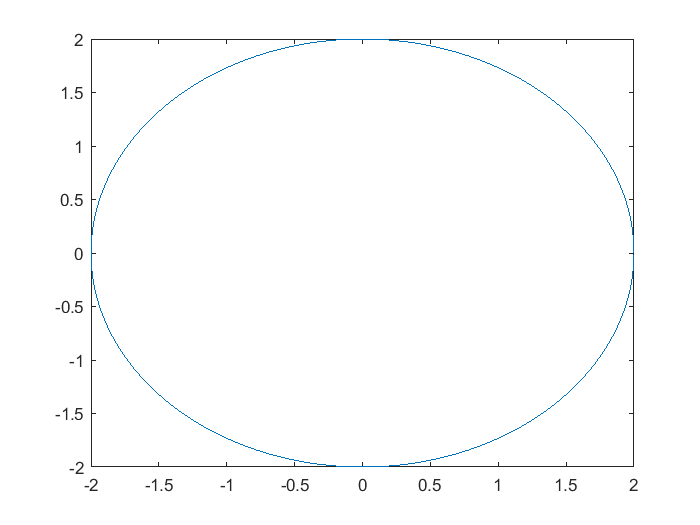

delta_phi = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    z(i) = R*sind(delta_phi*(i-1));
    x(i) = R*cosd(delta_phi*(i-1));
end

plot(x,z)

Посчитаем t для каждого отрезка

for i = 1 : N
    if i == N
        tx(i) = ((x(1)-x(i)))/dx;
        tz(i) = ((z(1)-z(i)))/dx;
    else
        tx(i) = (x(i+1)-x(i))/dx;
        tz(i) = (z(i+1)-z(i))/dx;
    end
end

Посчитаем n для каждого отрезка

%   нормальный вектор найдем с помощью матрицы повороты
    a = -90;
    matrix = [cosd(a),-sind(a); sind(a),cosd(a)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Проверка

% for i = 1 : N
%     ans = dot(normal(i).n,tangent(i).t);
% end

Координаты центров отрезков

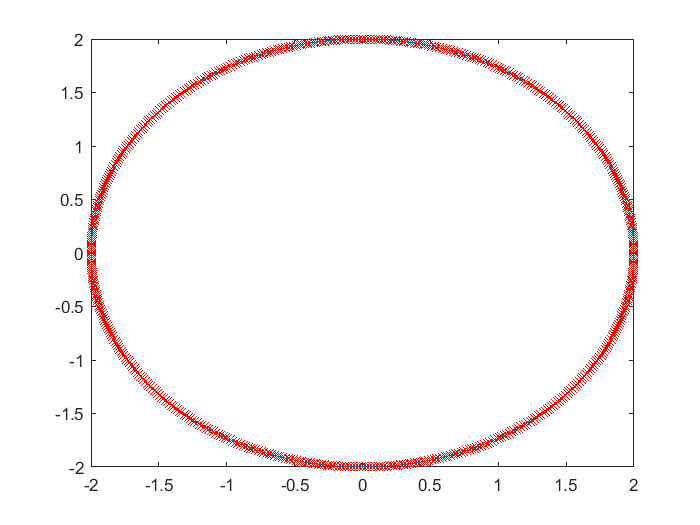

for i = 1 : N 
    if i == N
        x_midle(i) = ((x(1)+x(i)))/2;
        z_midle(i) = ((z(1)+z(i)))/2;
    else
        x_midle(i) = (x(i+1)+x(i))/2;
        z_midle(i) = (z(i+1)+z(i))/2;
    end    
end

plot(x,z,x_midle, z_midle, 'rx')

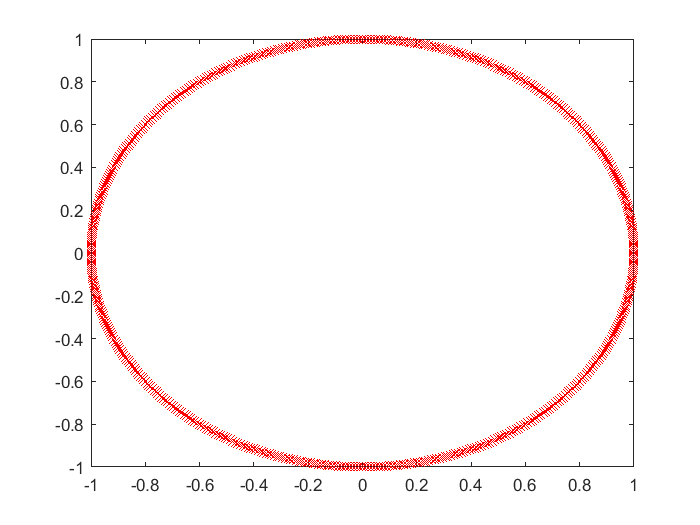


% визуализируем tx и tz
plot(tx, tz, 'rx')

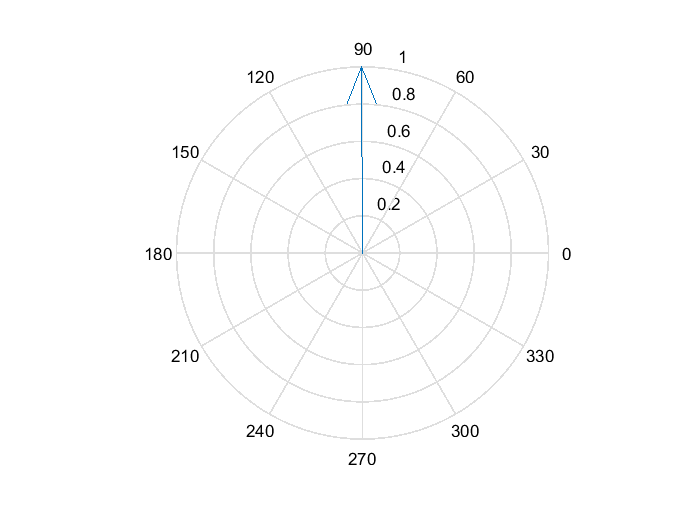

compass(tx(1),tz(1))

Изучим один цикл

count = 0;
for m = 1 : N
    
%   Координаты в исходной системе координат (в ГСК) 
% - т.к. точки находятся в центре отрезков разбиения
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
    %   Координаты в исходной системе координат (в ГСК)
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);

    %   Центр новой системы кооридны - начало отрезка (в ГСК)
%     
%         x_begin_O2 = x(n);
%         z_begin_O2 = z(n);

Давай возьмем середину отрезка

        x_begin_O2 = xn;
        z_begin_O2 = zn;
        
    %   Растояние между началом координат О2 и точкой наблюдений (в ГСК)
        x_mO2 = xm - x_begin_O2;
        z_mO2 =  zm - z_begin_O2;
         
%       Положим этот вектор на новую СК
%       Координаты этой точки (в ЛСК)
        xmO2 = x_mO2*txn + z_mO2*tzn;
        zmO2 = x_mO2*nxn + z_mO2*nzn;
        
    %   Растояние от n до точки m (в ЛСК)  
%         xmnO2 = xmO2 - dx/2;
%         zmnO2 = zmO2;
        

Т.к. взяли на начало середину отрезка то тут будет

        xmnO2 = xmO2;
        zmnO2 = zmO2;

%       Растояние между m и n (в ГСК)
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
%         r_test = sqrt(xmnO2^2 + zmnO2^2);
        
%       Расчет матричных элементов (в ЛСК)  
        if r < 0.001*dx
            Z = D0;
   
        elseif r <= treshold
%             k_xm_plus = k*(abs(xmnO2)+delta);
%             k_xm_minus = k*(abs(xmnO2)-delta);
%             Z = kdx +(1i*2/pi)*( k_xm_plus*log(gamma*k_xm_plus/2)-k_xm_minus*log(gamma*k_xm_minus/2)-kdx );
            
            xmn_plus_delta = (xmnO2) + delta;
            xmn_minus_delta = (xmnO2) - delta;
            r_plus_delta = sqrt(xmn_plus_delta^2 + zmnO2^2);
            r_minus_delta = sqrt(xmn_minus_delta^2 + zmnO2^2);
%             zmn = abs(zmnO2);
%             Z = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(asin(xmn_plus_delta/r_plus_delta)- asin(xmn_minus_delta/r_minus_delta)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);
            zmn = zmnO2;
            Z = kdx+k*2*1i/pi*(dx*log(gamma*k/2)-dx*zmn*(atan(xmn_plus_delta/zmn)- atan(xmn_minus_delta/zmn)) + 0.5*xmn_plus_delta*log(r_plus_delta^2)  -  0.5* xmn_minus_delta*log(r_minus_delta^2)- dx);

        else
            f2 = besselh(0,1,k*r);
            Z = k*dx*f2;
        end
        
        r_x_plus = sqrt((xmnO2+delta)^2+zmnO2^2);
        r_x_minus = sqrt((xmnO2-delta)^2+zmnO2^2);
        
        Esx= (xmnO2-delta)/r_x_minus*besselh(1, 1, k*r_x_minus) - (xmnO2+delta)/r_x_plus*besselh(1, 1, k*r_x_plus) + Z;
        Esz = (zmnO2)/r_x_minus*besselh(1, 1, k*r_x_minus) - (zmnO2)/r_x_plus*besselh(1, 1, k*r_x_plus);        

        tx_betven_vectors = tx(m)*tx(n) + tz(m)*tz(n);
        tz_betven_vectors = tx(m)*nx(n) + tz(m)*nz(n);
        
        Es(m,n) = Esx*tx_betven_vectors + Esz*tz_betven_vectors;
            

    end
end
 

Расчет падающего поля

for m=1:N
    cx = -1i*k*cosd(phi_grad);
    cz = -1i*k*sind(phi_grad);
    % Определим координаты
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    
%   Итоговое падающее поел - это суперпозиция полей
    Eix = +4*1i*sind(phi_grad)*exp(cx*xm+cz*zm);% падающее поле X
    Eiz = -4*1i*cosd(phi_grad)*exp(cx*xm+cz*zm);% падающее поле Z
    Ei(m,1) = Eix*txm + Eiz*tzm; 
end

Посчитаем токи и построим график

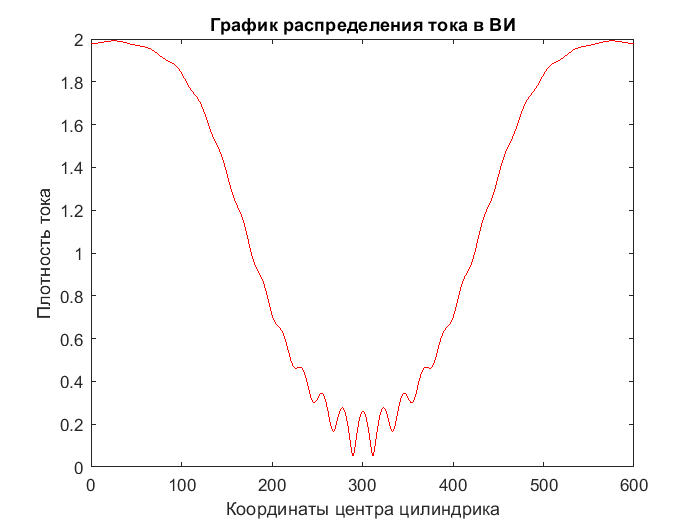

% расчеток токов ВИ 
I=Es\Ei;
       
% номера ВИ для графика 
n_for_graf = zeros(1, N);
for i = 1 : N
     n_for_graf(i) = i;
end

% построение графика респределения токов в ВИ

figure;
plot(n_for_graf, abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');

Сделаем счетчик для графика в градусах

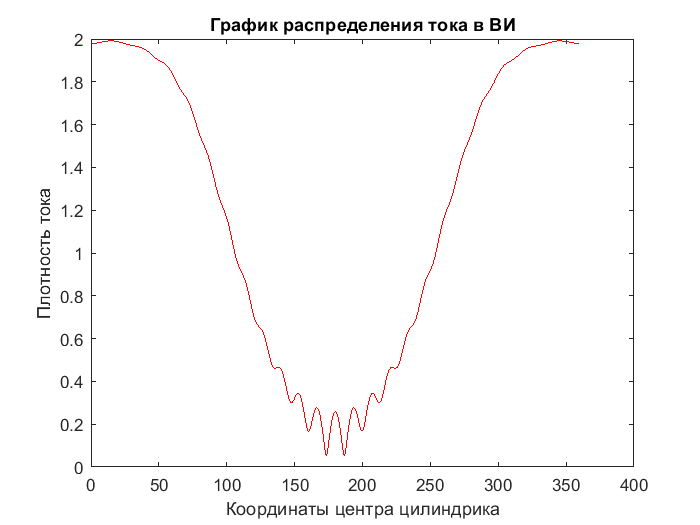

% Берем угол точки в середине отрезка
begin_phi = delta_phi/2;
phi_for_graf = [];
for i = 1 : N 
    count = begin_phi + delta_phi*(i-1);
    phi_for_graf(i) = count;
end

figure;
fig = plot(phi_for_graf, abs(I), 'r');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');

saveas(fig, 'MySimulinkDiagram.bmp')

Запись в файл

for n=1:N
    Inorm = abs(I/120/pi*1000);
    fprintf(f01,' %10.5f %10.5f\n', phi_for_graf(n), Inorm(n));
end

fclose(f01);